# Lab 2 DC Motor 

clear; clc;
sim = sim('Ex2Week1Simupdate.slx');

# Below Consists of What to turn in for Final Report

### Simulations Closed Loop Step Responses (Lin & Nonlin)

The previous open loop simulink model was modified to represent a closed loop model. This was done by adding an output potentiometer in a feedback path that connected the output position theta to the correct input of the op-amp summing amplifier. 

% figure()
% plot(sim.tout,sim.nonlinfeedback,"b")
% hold on
% plot(sim.tout,sim.linfeedback_Fixed,'color',[.5 0 .5])
% plot(sim.tout,sim.nonlinfeedback_tuned,"c")
% title(["Simulink Models of Closed-Loop Position Feedback","Control of DC Motomatic Motor with 180 Degree Input Knob"])
% ylabel("Position [degrees]")
% xlabel("time [seconds]")
% legend("Non-Linear Model before Tuning", "Linear Model before Tuning","Non-Linear Tuned")
% xlim([0 6])
% grid on
% hold off

% figure()
% plot(sim.tout,sim.linfeedback_Fixed,'color',[.5 0 .5])
% title(["Simulink Model of Linear Closed-Loop Position Feedback","Control of DC Motomatic Motor with 180 Degree Input Knob","before tuning"])
% ylabel("Position [degrees]")
% xlabel("time [seconds]")
% xlim([0 6])
% grid on
% hold off

% figure()
% plot(sim.tout,sim.nonlinfeedback,"b")
% title(["Simulink Model of NonLinear Closed-Loop Position Feedback","Control of DC Motomatic Motor with 180 Degree Input Knob","before tuning"])
% ylabel("Position [degrees]")
% xlabel("time [seconds]")
% xlim([0 6])
% grid on
% hold off

% figure()
% plot(sim.tout,sim.nonlinfeedback_tuned,"c")
% title(["Simulink Model of Nonlinear Tuned Closed-Loop Position Feedback","Control of DC Motomatic Motor with 180 Degree Input Knob"])
% ylabel("Position [degrees]")
% xlabel("time [seconds]")
% xlim([0 6])
% grid on
% hold off

### Experimental & Sim Closed Loop Step Responses (All Nonlin)

The previous open loop simulink model w

Data_5K = '5K_data.xlsx' ; % Retrieves Excel File with Data 
data_5k = readtable(Data_5K) ; % Reads Experimental Data for CL Feedback 

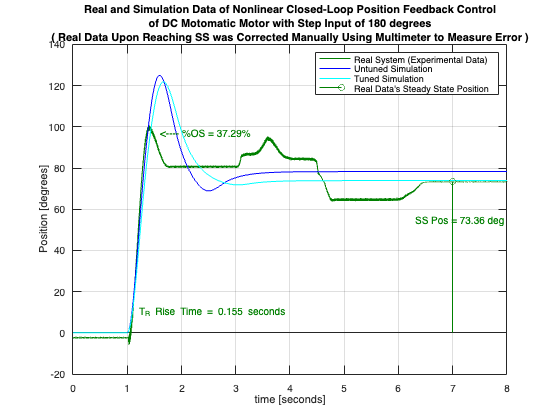

% Extract the data for plotting
time_5k = data_5k(:,4) ; % Time in seconds
timeArrray_5k=table2array(time_5k) ; 
position_5k = data_5k(:,3) ; % Position in Degrees
posArray_5k = table2array(position_5k) ;

% Calculating % Overshoot
OS_5k = ((max(posArray_5k)-posArray_5k(end))/posArray_5k(end))*100 ;
% SS Position
SS_5k = (posArray_5k(end)) ;
% Calculating Rise Time
Tr_pt9_5k = ((posArray_5k(end)).*0.9) ;
Tr_pt9_5k = ((posArray_5k(end)).*0.1) ;
Tr_5k = 1.244-1.089 ; % seconds

% Plot the experimental data
figure()
plot(timeArrray_5k, posArray_5k,'color', [0 0.5 0])
hold on
plot(sim.tout,sim.nonlinfeedback,"b")
plot(sim.tout,sim.nonlinfeedback_tuned,"c") % added gain block of 0.9
title(["Real and Simulation Data of Nonlinear Closed-Loop Position Feedback Control","of DC Motomatic Motor with Step Input of 180 degrees","( Real Data Upon Reaching SS was Corrected Manually Using Multimeter to Measure Error )"])
ylabel("Position [degrees]")
xlabel("time [seconds]")
xlim([0 8])
grid on

% Mark % OS on graph
text(1.6,97,'<---- %OS = 37.29%','color', [0 0.5 0])
% Mark SS Pos on graph
stem(7,SS_5k,'color', [0 0.5 0])
text(6.3,55,'SS Pos = 73.36 deg','color', [0 0.5 0])
% Mark Tr (Rise Time) on graph
text(1.2,10,'T_R Rise Time = 0.155 seconds','color', [0 0.5 0])

legend("Real System (Experimental Data)","Untuned Simulation","Tuned Simulation","Real Data's Steady State Position")
hold off

drop might be noise

- backemf is force

- seeing data which tells where pos is

- some discrepancy between where 

- noise from voltage signals

- spring back maybe from 

- wind up

## Real System OL Step Response to find Tau

The following shows the step repsonse of the DC Motor collected during lab. 

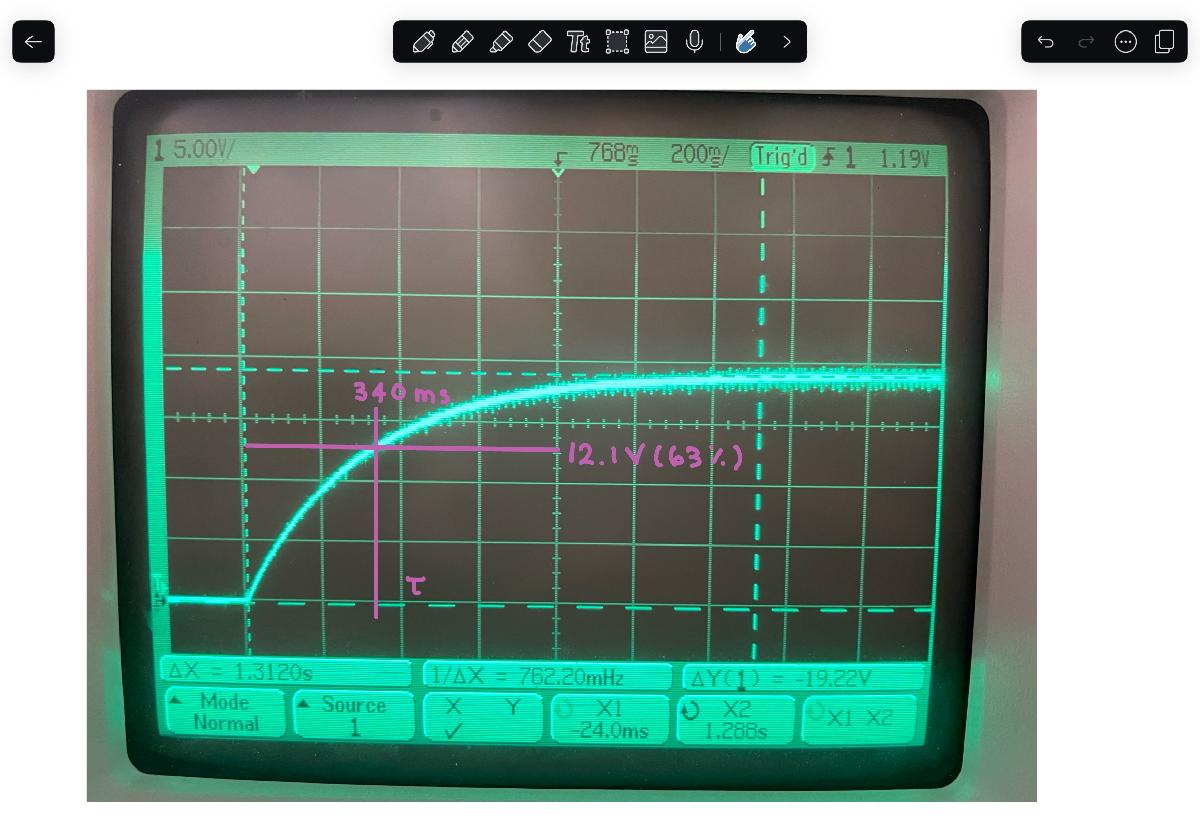

The gain is 19.22 Volts. 

Tau_Location = 0.63*19.22

Tau_Location = 12.1086

The location of the time constant, Tau, sits at 63% of the gain. This is at 12.1086 Volts. By observation, the time response sits at about 0.34 seconds into the step response curve. 

### Simulation Open Loop Step Responses

The constant, Km,lin, was determined for the linear model by making an estimate of the "average" slope of the wm vs VA data collected during lab. The linear model uses Km,lin as the motor constant. 

The constant Km for the nonlinear model was determined by finding the slope of the wm vs VA data  outside of the deadband area. 

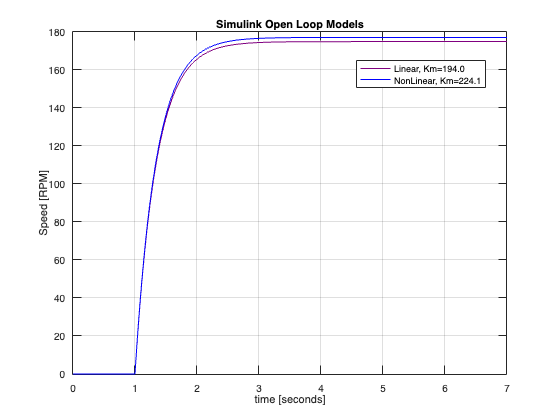

figure()
plot(sim.tout,sim.Linear,'color',[.5 0 .5])
hold on
plot(sim.tout,sim.nonlinear,'b')
title(["Simulation Open-Loop Step Response of Linear and Nonlinear Models"])
ylabel("Speed [RPM]")
xlabel("time [seconds]")
legend("Linear, Km=194.0","NonLinear, Km=224.1")
legend("Position", [0.63758,0.79309,0.23036,0.063095])
grid on
xlim([0 7])
hold off

## Controller Gain Response Test - Comparing Measured and Linear Model Step Response for 3 Amplifier Gains

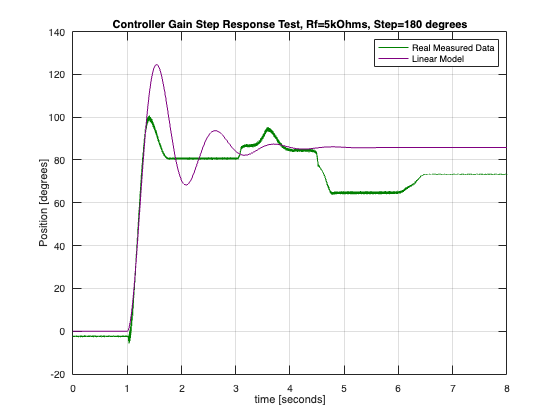

figure()
plot(timeArrray_5k, posArray_5k,'color', [0 0.5 0])
hold on
plot(sim.tout,sim.linfeedback_Fixed,'color',[.5 0 .5])
grid on
xlim([0 8])
title('Controller Gain Step Response Test, Rf=5kOhms, Step=180 degrees')
ylabel("Position [degrees]")
xlabel("time [seconds]")
legend("Real Measured Data","Linear Model")
hold off

Data_10K = '10K_data.xlsx' ; % Retrieves Excel File with Data 
data_10k = readtable(Data_10K) ; % Reads Experimental Data for CL Feedback 

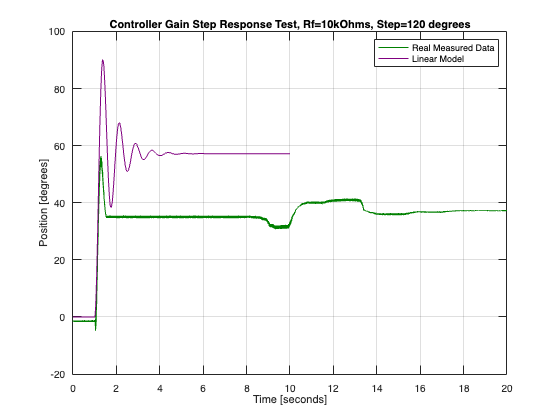

% Extract the data for plotting
time_10k = data_10k(:,4) ; % Time in seconds

timeArrray_10k=table2array(time_10k) ; 
position_10k = data_10k(:,3) ; % Position in Degrees
posArray_10k = table2array(position_10k) ;

figure()
plot(timeArrray_10k, posArray_10k,'color', [0 0.5 0])
hold on
plot(sim.tout,sim.linfeedback_10k,'color',[.5 0 .5])
grid on
xlim([0 20])
title('Controller Gain Step Response Test, Rf=10kOhms, Step=120 degrees')
ylabel("Position [degrees]")
xlabel("Time [seconds]")
legend("Real Measured Data","Linear Model")
hold off

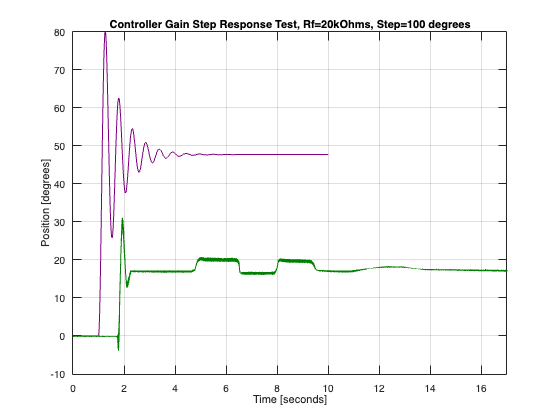

% 20 K Data
Data_20k=load('20K_NEWNEW.mat') ;
Data_processed_20k = Data_20k.data{2}.Values ;
Time_20k = Data_processed_20k.Time(20000:end,:)-Data_processed_20k.Time(20000,:) ;
Pos_20k = Data_processed_20k.Data(20000:end,:) ;

figure()
plot(sim.tout,sim.linfeedback_20k,'color',[.5 0 .5])
hold on
plot(Time_20k,Pos_20k,'color', [0 0.5 0])
grid on
title('Controller Gain Step Response Test, Rf=20kOhms, Step=100 degrees')
ylabel("Position [degrees]")
xlabel("Time [seconds]")
xlim([0 17])
hold off